# Q1 Download the wine data set from the UCI database.  Train a network with 2 hidden units on the data, holding out 10 items from each category for testing.

% set up
clear;
rs = rand()*100000

rs =         38478

% obtain data
wine = str2num(urlread("https://archive.ics.uci.edu/ml/machine-learning-databases/wine/wine.data"));
% turn 1,2,3 output to [1 0 0], [0 1 0], [0 0 1]
data = [dummyvar(categorical(wine(:,1))) wine(:,2:end)];

% catalog data to test_set(10), and training_set(whatever left)
test_set = [];
valid_set = [];
for i = 1:3 % for each category
    cat_wine = data(data(:, i) > 0, :)
    % Randomly select unrepeatable 10 item for testing
    indexes = randperm(size(cat_wine, 1), 20)
    test_set = [test_set; cat_wine(indexes(:,1:10), :)];
    valid_set = [valid_set; cat_wine(indexes(:,11:20), :)];
end

cat_wine =             1            0            0        14.23         1.71         2.43         15.6          127          2.8         3.06         0.28         2.29         5.64         1.04         3.92         1065
            1            0            0         13.2         1.78         2.14         11.2          100         2.65         2.76         0.26         1.28         4.38         1.05          3.4         1050
            1            0            0        13.16         2.36         2.67         18.6          101          2.8         3.24          0.3         2.81         5.68         1.03         3.17         1185
            1            0            0        14.37         1.95          2.5         16.8          113         3.85         3.49         0.24         2.18          7.8         0.86         3.45         1480
            1            0            0        13.24         2.59         2.87           21          118          2.8         2.69         0.39         1

indexes =     33     1    49    39    51    28    43    22    41    42    32    58    46    47    18    15    52    36    14     4


cat_wine =             0            1            0        12.37         0.94         1.36         10.6           88         1.98         0.57         0.28         0.42         1.95         1.05         1.82          520
            0            1            0        12.33          1.1         2.28           16          101         2.05         1.09         0.63         0.41         3.27         1.25         1.67          680
            0            1            0        12.64         1.36         2.02         16.8          100         2.02         1.41         0.53         0.62         5.75         0.98         1.59          450
            0            1            0        13.67         1.25         1.92           18           94          2.1         1.79         0.32         0.73          3.8         1.23         2.46          630
            0            1            0        12.37         1.13         2.16           19           87          3.5          3.1         0.19         1

indexes =     69    33    47    20    32    63    66    44    64    17     2     7    36    65    29    40    26    54    18     1


cat_wine =             0            0            1        12.86         1.35         2.32           18          122         1.51         1.25         0.21         0.94          4.1         0.76         1.29          630
            0            0            1        12.88         2.99          2.4           20          104          1.3         1.22         0.24         0.83          5.4         0.74         1.42          530
            0            0            1        12.81         2.31          2.4           24           98         1.15         1.09         0.27         0.83          5.7         0.66         1.36          560
            0            0            1         12.7         3.55         2.36         21.5          106          1.7          1.2         0.17         0.84            5         0.78         1.29          600
            0            0            1        12.51         1.24         2.25         17.5           85            2         0.58          0.6         1

indexes =      9     2    15    41    35    24    38     6    34    37    30    13    46    33    25    44    40    22    42     1


% training = original - test
train_set = setdiff(data, [test_set; valid_set], "rows");
isequal(sortrows(data),sortrows([train_set;valid_set;test_set])) % sanity check

ans = logical
   1


% reshape data
training.smat = train_set(:,4:end);
training.tmat = train_set(:,1:3);

testing.smat = test_set(:,4:end);
testing.tmat = test_set(:,1:3);

validation.smat = valid_set(:,4:end);
validation.tmat = valid_set(:,1:3);

## a. Show the error curves over time

% init random 1 layer network with stimulus(13) input, 2 hidden, and 3 output
q1net0 = initnet3(13,2,3,1,1,rs)

q1net0 = struct with fields:
      wih: [2×13 double]
    hbias: [0.0071841 -0.26424]
    whout: [3×2 double]
    obias: [0.27257 -0.48118 -0.29976]

q1net0.wih

ans =      -0.46122      0.49896      0.25521      0.49253     -0.44605     -0.32404     -0.42929      0.30011     0.036105     0.026642     -0.15557      0.37808     -0.19646
      0.21855      0.29365      0.10804       -0.348    -0.044362      0.24306      -0.3088      0.44005     -0.05879     -0.23149     -0.17114     0.080429      0.38981


q1net0.whout

ans =      -0.30485     0.072007
      0.40582     -0.04996
     -0.34411     -0.16079


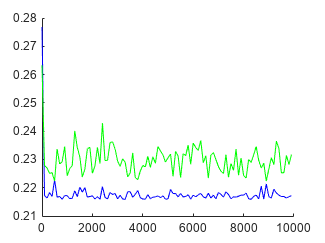


niter = 10000; % n-th iteration
eta = 0.02; % Eta, learning rate
nlev = 0; % noise level
[bestnet,finalnet,errmat] = bp3trvats(q1net0,training,validation,testing,niter,eta,nlev,.01);

figure
err = errmat(1:niter/100:niter,:);
hold on
plot(err(:,1),err(:,2),'b')
plot(err(:,1),err(:,3),'r')
plot(err(:,1),err(:,4),'g')
hold off

## b. Show the final confusion matrix (3 categories)

target = data(:,1:3);
stim = data(:,4:end);
pats.smat = stim;
pats.tmat = target;

bestact=forw3(bestnet, pats)

bestact = struct with fields:
    stim: [178×13 double]
     hid: [178×2 double]
     out: [178×3 double]

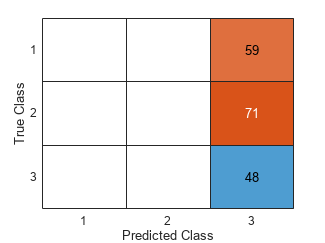

% build confusion matrix
[~,t] = max(target, [], 2);
[~,o] = max(bestact.out,[],2);
figure
confusionchart(t,o)

## c. Plot the hidden unit representations using different colors for the wine type.

act = forw3(bestnet,pats)

act = struct with fields:
    stim: [178×13 double]
     hid: [178×2 double]
     out: [178×3 double]

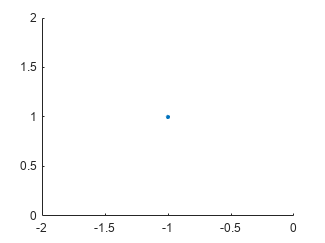

act.hid;
color = [training.tmat,zeros(size(training.tmat)),1-training.tmat];
scatter(act.hid(:,1),act.hid(:,2),10,"filled")

## Q2 The following table summarizes BMI data from 300 patients, of which 100 have been diagnosed with breast cancer.

%{
BMI (kg/m3)   <18 18-20 20-22 22-24 24-26 26-28 28-30 30-32 32-34 34-36 36-38 38-40
Cancer (n=100) 0    1     4    10    19    19    13    13     4    10     6     1
No Cancer	   2   21    60    37    27    26    10     3     8     2     3     1
%}

bmi = [	"<18"	"18-20"	"20-22"	"22-24"	"24-26"	"26-28"	"28-30"	"30-32"	"32-34"	"34-36"	"36-38"	"38-40"];
cancer = [0	1	4	10	19	19	13	13	4	10	6	1];
no_cancer = [2	21	60	37	27	26	10	3	8	2	3	1];

## a. Compute the number of true positives, true negatives, false positives and false negatives at each BMI level.

cdata = []

cdata =
     []


b = 18;
for i=1:length(bmi)
    cdata = [cdata; [b sum(cancer(:,i+1:end)) sum(cancer(:,1:i)) sum(no_cancer(:,i+1:end)) sum(no_cancer(:,1:i))]];
    b = b+2;
end
["bmi_cutoff" "tp" "tn" "fp" "fn"; cdata]

ans = 13×5 string array
    "bmi_cutoff"    "tp"     "tn"     "fp"     "fn" 
    "18"            "100"    "0"      "198"    "2"  
    "20"            "99"     "1"      "177"    "23" 
    "22"            "95"     "5"      "117"    "83" 
    "24"            "85"     "15"     "80"     "120"
    "26"            "66"     "34"     "53"     "147"
    "28"            "47"     "53"     "27"     "173"
    "30"            "34"     "66"     "17"     "183"
    "32"            "21"     "79"     "14"     "186"
    "34"            "17"     "83"     "6"      "194"
    "36"            "7"      "93"     "4"      "196"
    "38"            "1"      "99"     "1"      "199"
    "40"            "0"      "100"    "0"      "200"

## b. Construct an ROC curve.

tpr = [];
fpr = [];
for i = 1:size(cdata,1)
    tpr = [tpr; cdata(i,2)/100];
    fpr = [fpr; cdata(i,4)/200];
end
["tpr" "fpr"; tpr fpr]

ans = 13×2 string array
    "tpr"     "fpr"  
    "1"       "0.99" 
    "0.99"    "0.885"
    "0.95"    "0.585"
    "0.85"    "0.4"  
    "0.66"    "0.265"
    "0.47"    "0.135"
    "0.34"    "0.085"
    "0.21"    "0.07" 
    "0.17"    "0.03" 
    "0.07"    "0.02" 
    "0.01"    "0.005"
    "0"       "0"    

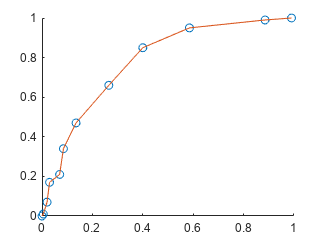

figure 
hold on
scatter(fpr,tpr)
plot(fpr,tpr)
hold off

## c. How would you generate an approximate boxplot for the two categories?

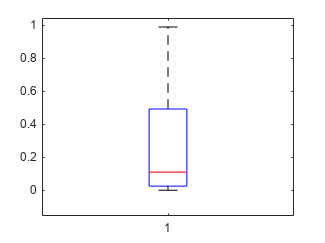

boxplot(fpr)

boxplot(fpr)

## 3.  The code below constructs and displays a training set and test set for a simple 2-D classification task.

## a. Paste the code into Matlab to generate pattern sets train and test.

train.smat=2*rand(30,2)-1

train = struct with fields:
    smat: [30×2 double]

dtrain = sqrt(diag(train.smat*train.smat'));
train.tmat=(dtrain<.85).*(dtrain>.45)

train = struct with fields:
    smat: [30×2 double]
    tmat: [30×1 double]

ktrain=[train.tmat,zeros(30,1),1-train.tmat];
figure
scatter(train.smat(:,1),train.smat(:,2),300,ktrain,'filled')
test.smat=2*rand(20,2)-1

test = struct with fields:
    smat: [20×2 double]

dtest = sqrt(diag(test.smat*test.smat'));
test.tmat=(dtest<.85).*(dtest>.45)

test = struct with fields:
    smat: [20×2 double]
    tmat: [20×1 double]

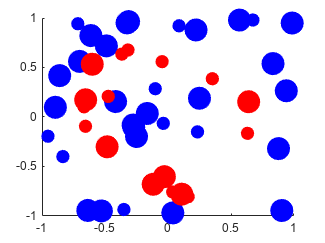

ktest=[test.tmat,zeros(20,1),1-test.tmat];
hold on
scatter(test.smat(:,1),test.smat(:,2),100,ktest,'filled')

## b. Initialize a network with 4 hidden units, and run bp3 for n iterations (where 10000<n<20000) at a learning rate dt (where .02 < dt < .2) using the pattern set train.

% init network
q3net0 = initnet3(2,4,1,2,2,rs);
% train
q3net10k = bp3(q3net0,train,10000,.1,0,rs)

q3net10k = struct with fields:
      wih: [4×2 double]
    hbias: [-0.31314 -0.1437 0.38205 2.3729]
    whout: [-0.56022 -1.1247 0.94539 1.8416]
    obias: -2.6347

## c. Use forw3 to test the final network on the test pattern set.

% applying the testing pattern to the trained network
testresult = forw3(q3net10k,test)

testresult = struct with fields:
    stim: [20×2 double]
     hid: [20×4 double]
     out: [20×1 double]

testresult.hid

ans =       0.35525     -0.93889      -0.2744      0.95671
     -0.38583     -0.52804      -0.2246      0.98669
       0.4731     -0.27188       0.4848     -0.30657
      0.49669     -0.79028       0.1558      0.54584
      0.32434     -0.75988     0.057791      0.78735
      0.28685     -0.82233    -0.052407      0.88261
     -0.13976     -0.18754      0.14215      0.86038
      0.18279     0.080032      0.45468     0.092891
     -0.30166      -0.6235     -0.23228      0.98472
    -0.064993     -0.90347     -0.42257      0.99191


testresult.out

ans =       0.43158
      0.44522
      0.06296
       0.2949
      0.38764
      0.42684
      0.34827
     0.097421
      0.45743
      0.46131


## d. Generate an ROC curve from the responses to the test set.

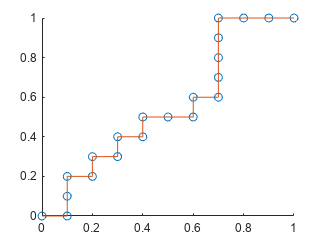

[tpr,fpr,thresholds]=roc(test.tmat', testresult.out');
figure 
hold on
scatter(fpr,tpr)
plot(fpr,tpr)

## Attachements

function [bestnet,finalnet,errmat]=bp3trvats(net0,trlist,valist,tslist,niter,eta,nlev,eps)
netk=net0;
maxiter=niter;
ase=2*eps ; % not use in this function
valbest=10;
i=0 ;
errmat=[] ;
while ((ase>eps)&&(i<maxiter))
    netk=cyc3(netk,trlist,eta,nlev) ; % Training procedure
    
    activ=forw3(netk,trlist) ;
    diff = trlist.tmat-activ.out;
    sse=sum(sum(diff.*diff));
    trerr=sse/numel(diff) ; % Training error

    activ=forw3(netk,valist) ;
    diff = valist.tmat-activ.out;
    sse=sum(sum(diff.*diff));
    valerr=sse/numel(diff) ; % Validation error
    if (valerr<valbest)
        % Save the network with the lowest validation error
        ibest=i ;
        valbest=valerr;
        bestnet=netk;
    end

    activ=forw3(netk,tslist) ;
    diff = tslist.tmat-activ.out;
    sse=sum(sum(diff.*diff));
    tserr=sse/numel(diff) ; % Test error

    errmat=[errmat;[i,trerr,valerr,tserr]];
    i=i+1 ;
end
finalnet=netk;
finalnet.iter=i;
finalnet.err=ase;
bestnet.iter=ibest; % fixed
bestnet.err=valbest; % fixed
end